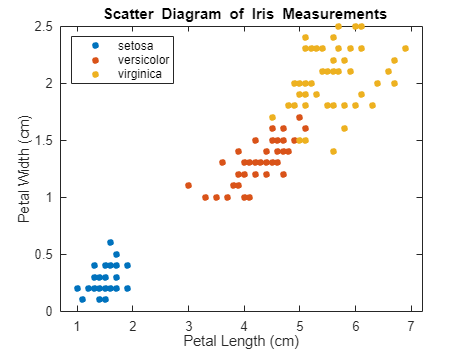

% 使用二类 SVM 计算多个类边界
% 创建 fisheriris 数据集的散点图。将图中网格的坐标点视为来自数据集分布的新观测值，并通过将坐标点分配给数据集中的三个类之一来找出类边界。
% 
% 加载 Fisher 鸢尾花数据集。使用花瓣长度和宽度作为预测变量。

load fisheriris
X = meas(:,3:4);
Y = species;
% 检查数据的散点图。

figure
gscatter(X(:,1),X(:,2),Y);
h = gca;
lims = [h.XLim h.YLim]; % Extract the x and y axis limits
title('{\bf Scatter Diagram of Iris Measurements}');
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');
legend('Location','Northwest');

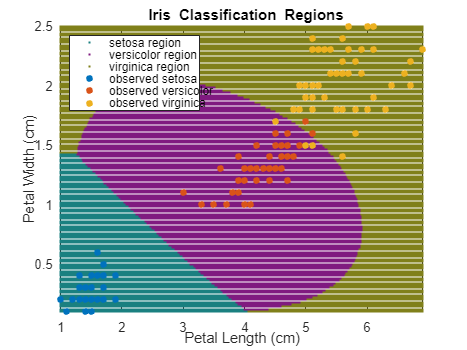


% 该数据包含三个类，其中一个类与其他类可线性分离。
% 对于每个类：
% 创建一个逻辑向量 (indx)，指示观测值是否为该类的成员。
% 使用预测变量数据和 indx 训练 SVM 分类器。
% 将该分类器存储在元胞数组的一个元胞中。
% 定义类顺序。

SVMModels = cell(3,1);
classes = unique(Y);
rng(1); % For reproducibility

for j = 1:numel(classes)
    indx = strcmp(Y,classes(j)); % Create binary classes for each classifier
    SVMModels{j} = fitcsvm(X,indx,'ClassNames',[false true],'Standardize',true,...
        'KernelFunction','rbf','BoxConstraint',1);
end
% SVMModels 是 3×1 元胞数组，其中每个元胞包含一个 ClassificationSVM 分类器。
% 对于每个元胞，正类分别是 setosa、versicolor 和 virginica。

% 在图中定义精细网格，并将坐标点视为来自训练数据分布的新观测值。
% 使用每个分类器估计新观测值的分数。

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
N = size(xGrid,1);
Scores = zeros(N,numel(classes));

for j = 1:numel(classes)
    [~,score] = predict(SVMModels{j},xGrid);
    Scores(:,j) = score(:,2); % Second column contains positive-class scores
end
% Scores 的每行包含三个分数。
% 分数最高的元素的索引是新类观测值最可能属于的类的索引。
% 将每个新观测值与给它最高分数的分类器相关联。

[~,maxScore] = max(Scores,[],2);
% 基于对应新观测值所属的类，在绘图区域中着色。

figure
h(1:3) = gscatter(xGrid(:,1),xGrid(:,2),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]);
hold on
h(4:6) = gscatter(X(:,1),X(:,2),Y);
title('{\bf Iris Classification Regions}');
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');
legend(h,{'setosa region','versicolor region','virginica region',...
    'observed setosa','observed versicolor','observed virginica'},...
    'Location','Northwest');
axis tight
hold off